Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Match to a waist (Section 3.6.2)

Volker Ziemann, 211115, CC-BY-SA-4.0

**Important: **requires the functions for the 4D calculations, available in the `chap3/4D` subdirectory from the zip file with all MATLAB scripts. Needed for `calcmat()` and `plot_betas(). `

Here we use the FODO cell with phase advances 60 and 90 degrred from a previous live script and just assign in to the `beamline`, before calculating all transfer matrices and calculating the periodic beam matrix `sigma0` with emittances set to unity, such that `sigma0` contains the Twiss parameters $\alpha$, $\beta$, and $\gamma$. 

clear all; close all
global beamline sigma0
addpath ./4D       % use the 4D software
%beamline=dlmread('fodo6090.bl'); % use this file for one cell
fodo=[1,	5,	0.2,	0;        % just the contents of that file
      2,	1,	0,	-1.4748;
      1,	10,	0.2,	0;
      2,	1,	0,	1.8082;
      1,	5,	0.2,	0];
beamline=fodo;
[Racc,spos,nmat,nlines]=calcmat(beamline);     % get matrices
Rturn=Racc(:,:,end);                           % the last one
sigma0=periodic_beammatrix(Rturn,1,1);         % get betas
beamline=repmat(fodo,3,1)                     % three cells

beamline =     1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -1.4748
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    1.8082
    1.0000    5.0000    0.2000         0
    1.0000    5.0000    0.2000         0
    2.0000    1.0000         0   -1.4748
    1.0000   10.0000    0.2000         0
    2.0000    1.0000         0    1.8082
    1.0000    5.0000    0.2000         0


Using this beamline will work, but some of the focal lengths will turn out to be rather small and, moreover, the beta functions in the last quads are very large. Often it helps to increase the space between the last quadrupole and the waist and we define the entire beamline to consist of three cells and the extra drift added to the end.

% extra_drift=[1,5,0.2,0];                       % define addl. drift
% beamline=[repmat(fodo,3,1);extra_drift]    % make beamline longer

Uncomment these two lines and see how the beta functions become much smaller.

The following two lines will change the repeat code of drift spaces, which would essentially move the quadrupoles closer together. Here 11 and 13 refer to the respective lines in the `beamline` where we change the repeat code. You can uncomment these lines to explore what happens later.

% beamline(11,2)=13;  % change quadrupole positions
% beamline(13,2)=2;

Now we are ready to find focal lengths of the four quadrupoles in the second and third fodo cell. Why do we need four quadrupoles? Well, we want to set the horizontal and vertical beta functions at the final position, which accounts for two degrees of freedom we want to control. That we want a waist additionally requires that $\alpha_x$ and $\alpha_y$ are zero. This accounts for two more degrees of freedom, which require two more quads to adjust. Thus we need four quadrupoles and `x0` contains the initial guesses. The call to fminsearch() in the next line minimizes the squared difference between the deesired and actual Twiss parameters, which is calculated in the function chisq_waist(). Finally we plot the beat functions with sigma0, the matched beam matrix for the 60-90 cells, used as starting beam.

x0=[-1,2.,-2,2];                                % starting guesses
[x,fval]=fminsearch(@chisq_waist,x0)            % minimze

x =    -2.1158    0.7894   -1.3240    0.7215


fval = 0.9839

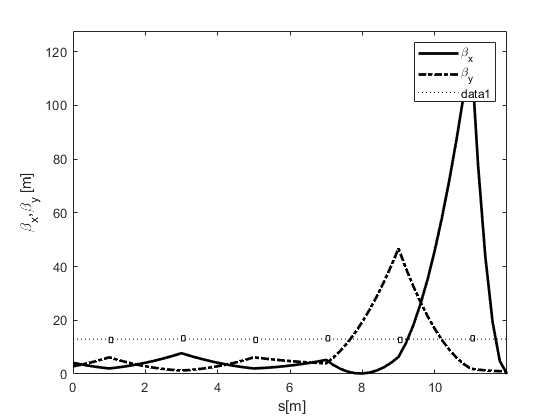

plot_betas(beamline,sigma0)                     % show betas
drawmag(beamline,12,2)

If we run without the `extra_drift`, we find that` fval` $\approx 1$and the beta functions are very large. Now uncomment the lines with the `extra_drift` added to the end of `beamline` and run again. Now we observe that the minimization succeeds with` fval` $\approx 10^{-8}$ and the plot shows that the beta functions are indeed close to 1 m. And finally, you can also uncomment the lines where we change the lengths of the drift spaces. Explore!

## chisq_waist()

This function receives the four focal lengths for the quadrupoles we use to adjust and sets these values in the appropriate slots of the beamline. Here line 7 refers to the first quad in the second cell and so forth. Once that is done, we calculate the transfer matrices with calcmat() and propagate the input beam sigma0 to the end. Finally, we calculate the chisq, which is the sum of the squared difference between sigma(1,1) and the desired beta function (1 m) and then adding the equivalent differences for the three other constraints.

function chisq=chisq_waist(x)
global beamline sigma0      % need info about the beamline
beamline(7,4)=x(1);         % set quadrupole focal lengths 
beamline(9,4)=x(2);
beamline(12,4)=x(3);        
beamline(14,4)=x(4);
[Racc,spos,nmat,nlines]=calcmat(beamline); Rend=Racc(:,:,end); 
sigma=Rend*sigma0*Rend';
chisq=(sigma(1,1)-1)^2+(sigma(3,3)-1)^2+sigma(1,2)^2+sigma(3,4)^2;
end